**Convolution vs correlation**

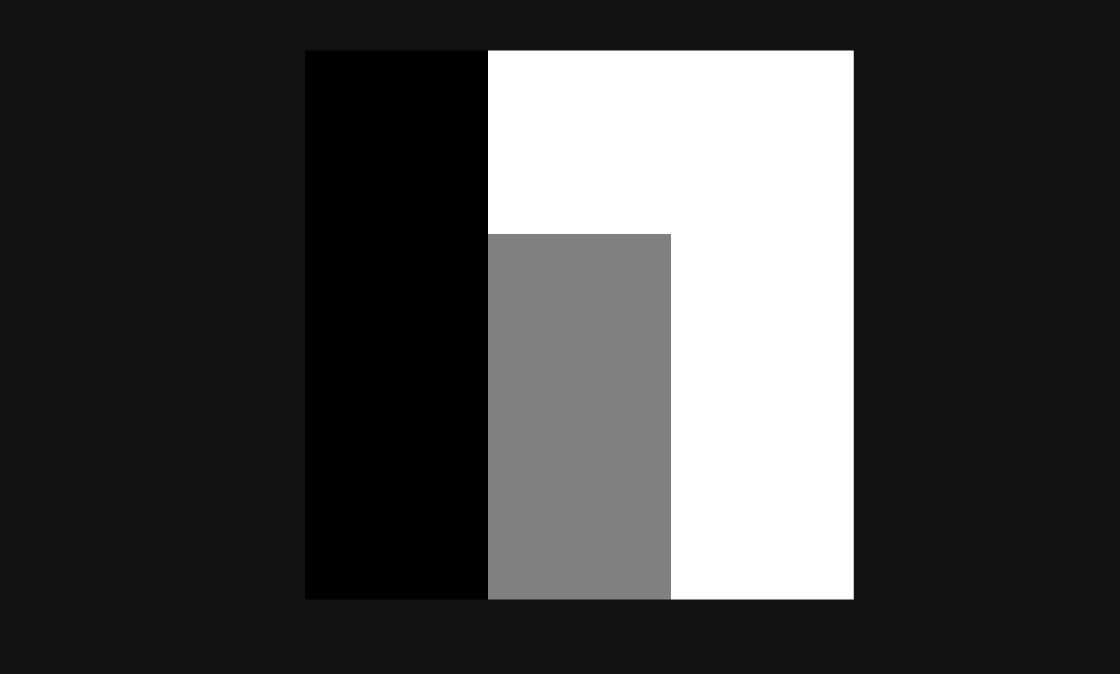

k1 = [-1 1 1; -1 0 1; -1 0 1];
imshow(k1, [])


% convolution
f = [8 9 8; 4 6 5; 1 2 1];
sum(sum(f .* k1))

ans = 10

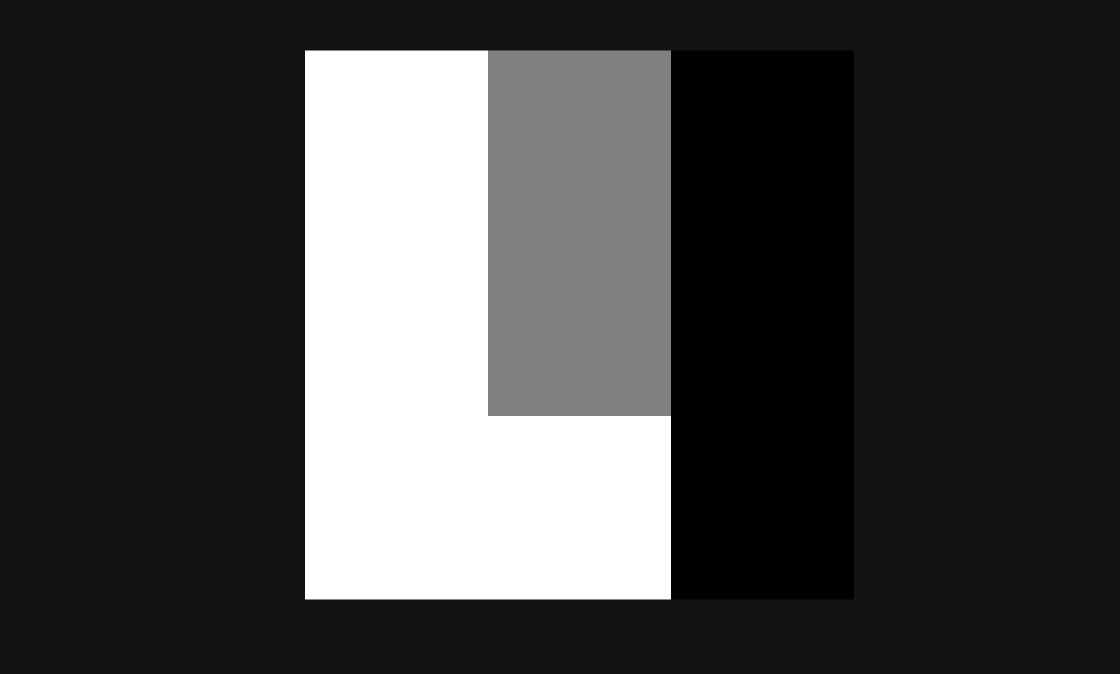


% correlation
k2 = rot90(k1, 2);
imshow(k2, [])

sum(sum(f .* k2))

ans = 1

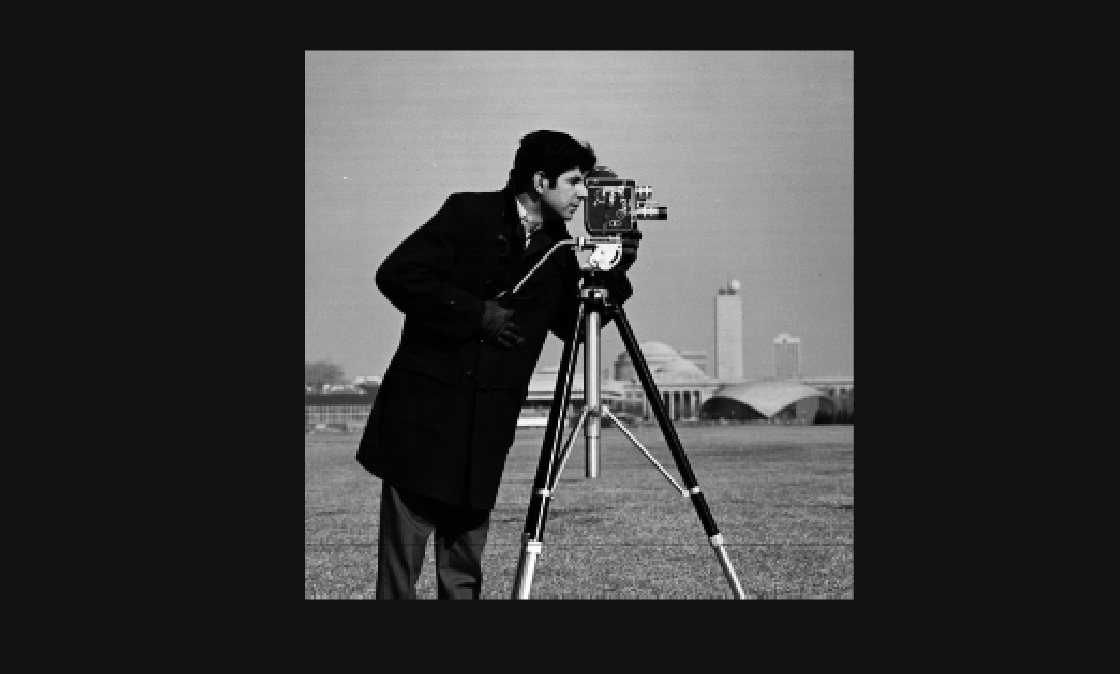



I = imread('cameraman.tif');
I = im2double(I);  
imshow(I, [])

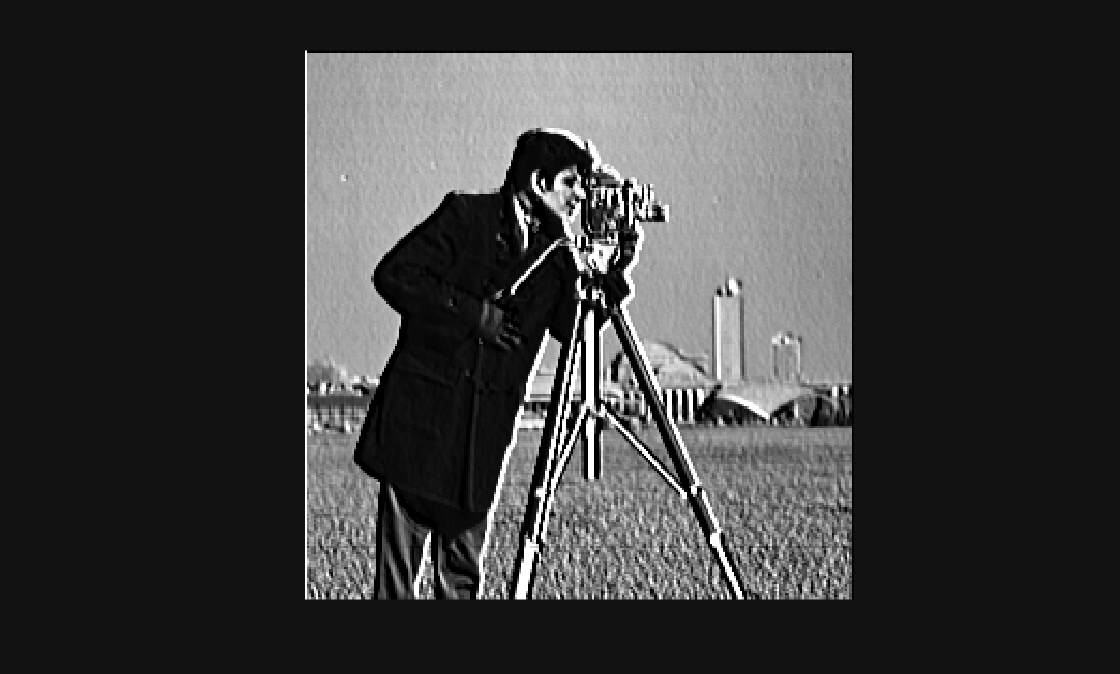


G_corr = imfilter(I, k1, 'corr'); imshow(G_corr)

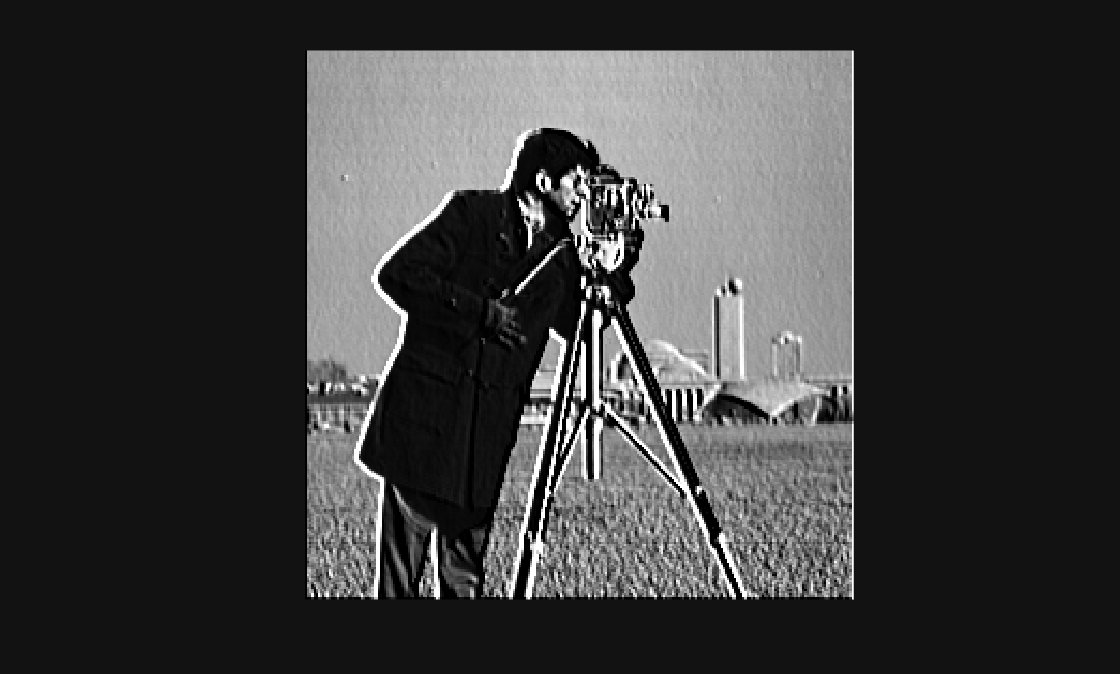

G_conv = imfilter(I, k1, 'conv'); imshow(G_conv)

**Common Filters**

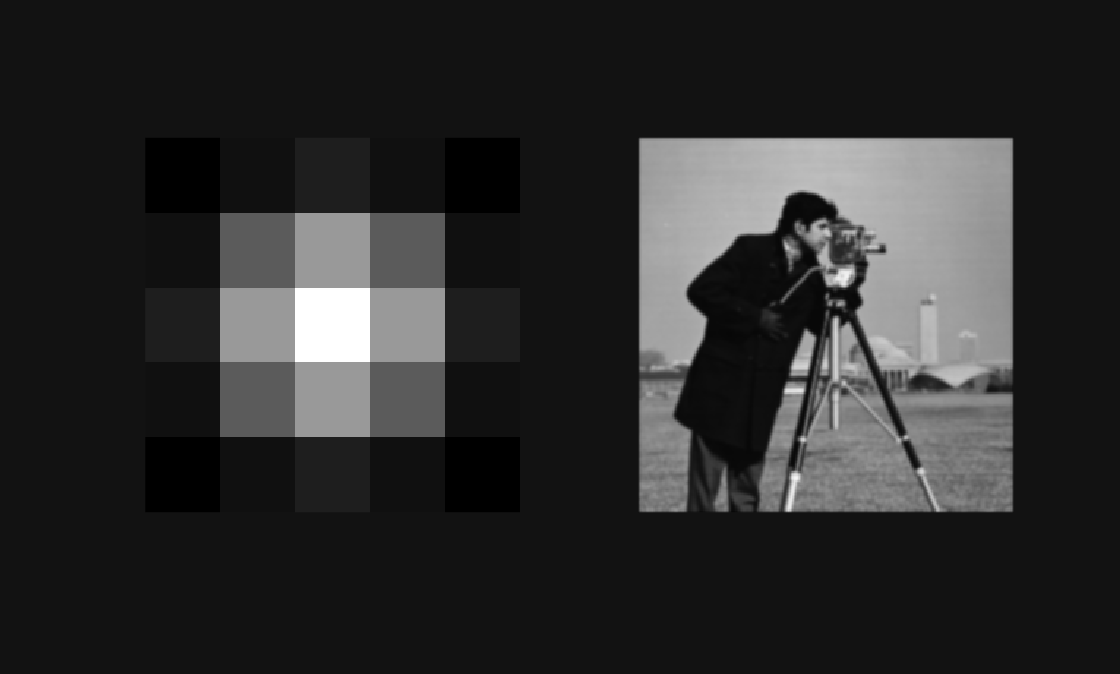


K_low_pass = ones(3) / 9;
K_identity = [0 0 0; 0 1 0; 0 0 0];
K_shift    = [0 0 0; 1 0 0; 0 0 0];
K_box      = ones(3)/9;
K_sharpen  = (1/9)*[-1 -1 -1; -1 17 -1; -1 -1 -1];
K_sobel_x  = [-1 0 1; -2 0 2; -1 0 1];
K_sobel_y  = [1 2 1; 0 0 0; -1 -2 -1];
K_prewitt_x = [-1 0 1; -1 0 1; -1 0 1];
K_line_h   = [-1 -1 -1; 2 2 2; -1 -1 -1];
K_line_v   = [-1 2 -1; -1 2 -1; -1 2 -1];
h_avg    = fspecial('average', 3);       
h_disk   = fspecial('disk', 7);   % out-of-focus
h_gauss  = fspecial('gaussian', [5 5], 1); 
h_motion = fspecial('motion', 20, 45);  % motion blur, 20px at 45 deg
h_sobel  = fspecial('sobel');            
h_laplacian = fspecial('laplacian');     


k = h_gauss; G = imfilter(I, k, 'conv'); 
subplot(1,2,1); imshow(k, []); subplot(1,2,2); imshow(G); figure;

**Noise and Denoising**

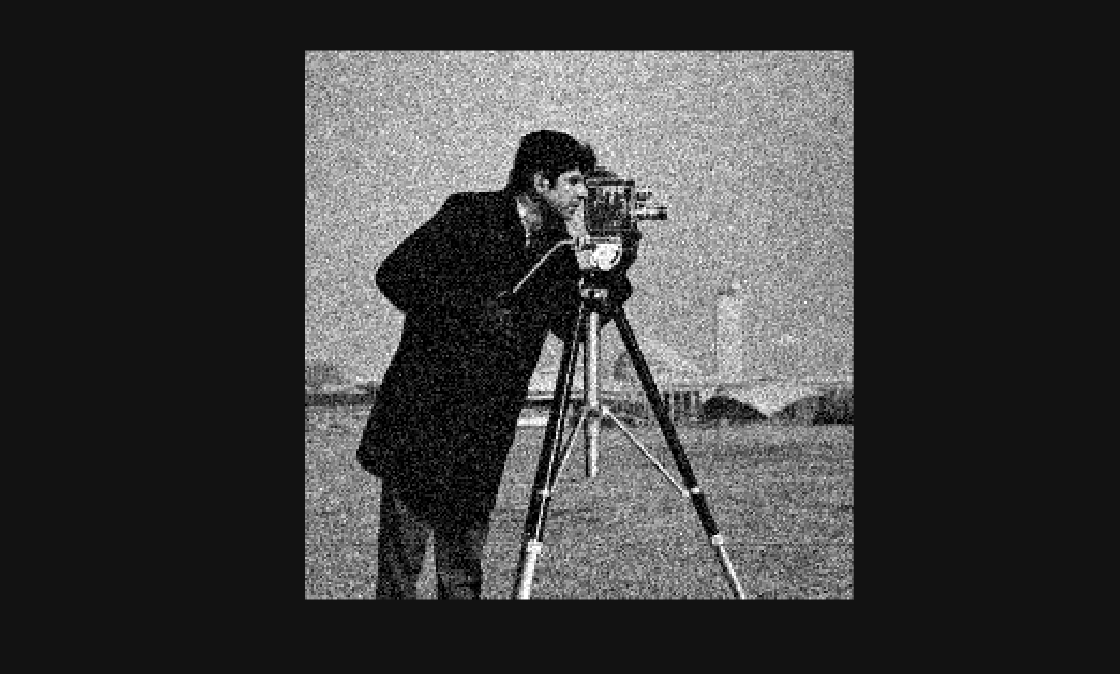


N = imnoise(I, "gaussian", 0.001, 0.01); imshow(N);

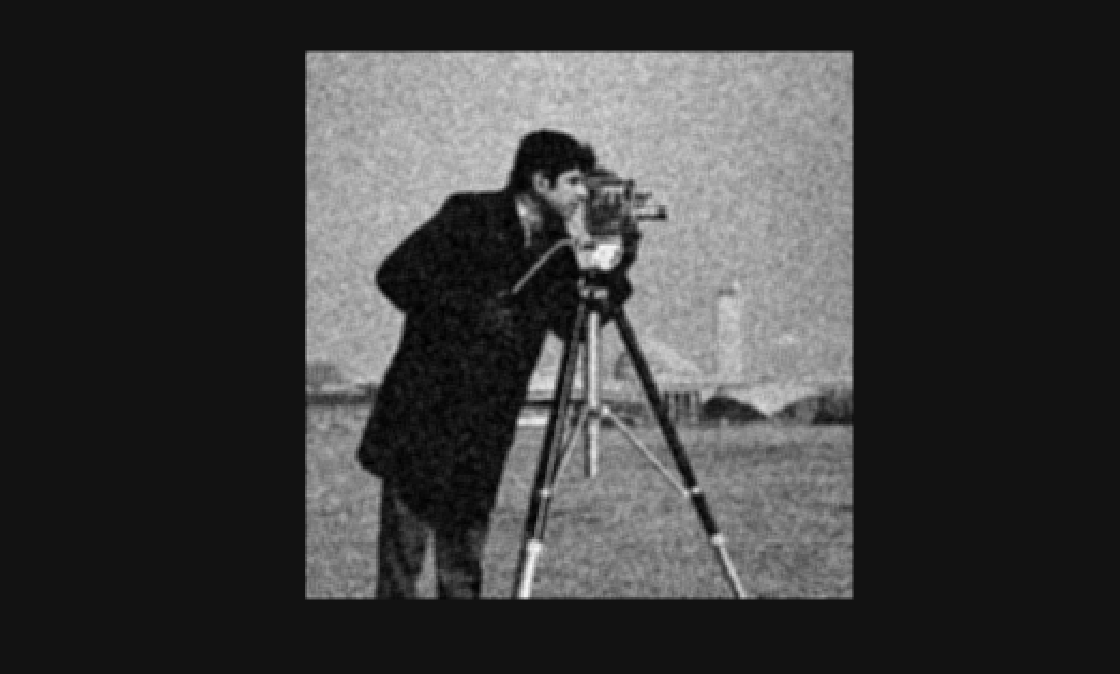

M = imfilter(N, K_low_pass, "conv"); imshow(M)

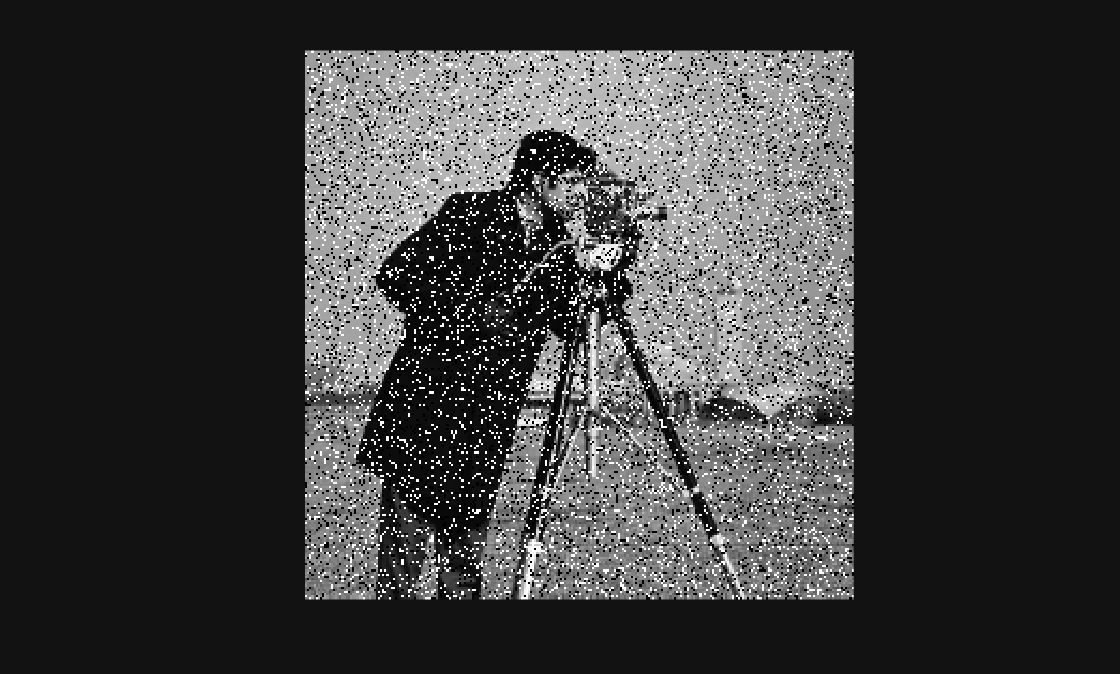

N = imnoise(I, "salt & pepper", 0.2); imshow(N);

N = medfilt2(N, [3 3]);imshow(M)